# First-level analysis with SPM12

### SPM orientation

SPM12 is software written in Matlab. It's one of the most popular packages for analyzing neuroimaging data (the top 3 are SPM, FSL, and AFNI), and the developers at UCL have made it free for everyone to use.

You can do most everything in two ways: By clicking buttons in the graphic interface (GUI), and by coding. SPM functions generally start with spm_<something>.  The GUI is a great way to get oriented, but when you run analyses for research--often on many participants--and want to have a reproducible, tracked workflow, coding is essential.  We'll start with the GUI for now, but we'll include a few code examples along the way.

Starting SPM brings up the graphics windows:

 ___  ____  __  __                                            
/ __)(  _ \(  \/  )                                           
\__ \ )___/ )    (   Statistical Parametric Mapping           
(___/(__)  (_/\/\_)  SPM12 - http://www.fil.ion.ucl.ac.uk/spm/


SPM12: v6906                                       16:34:04 - 05/05/2021
Initialising SPM                        :                   ..Item 'Confounds', field 'strtype': Value must be a valid strtype.
Item 'Confounds', field 'val': Size mismatch (required [1  100], present [1  1]).
Item 'Condition Labels', field 'strtype': Value must be a valid strtype.
Item 'Condition Labels', field 'val': Size mismatch (required [1  100], present [1  1]).
Duplicate application tag in applications 'SPM' and 'SPM'.
Duplicate application tag in applications 'BasicIO' and 'BasicIO'.
.

.

.

.

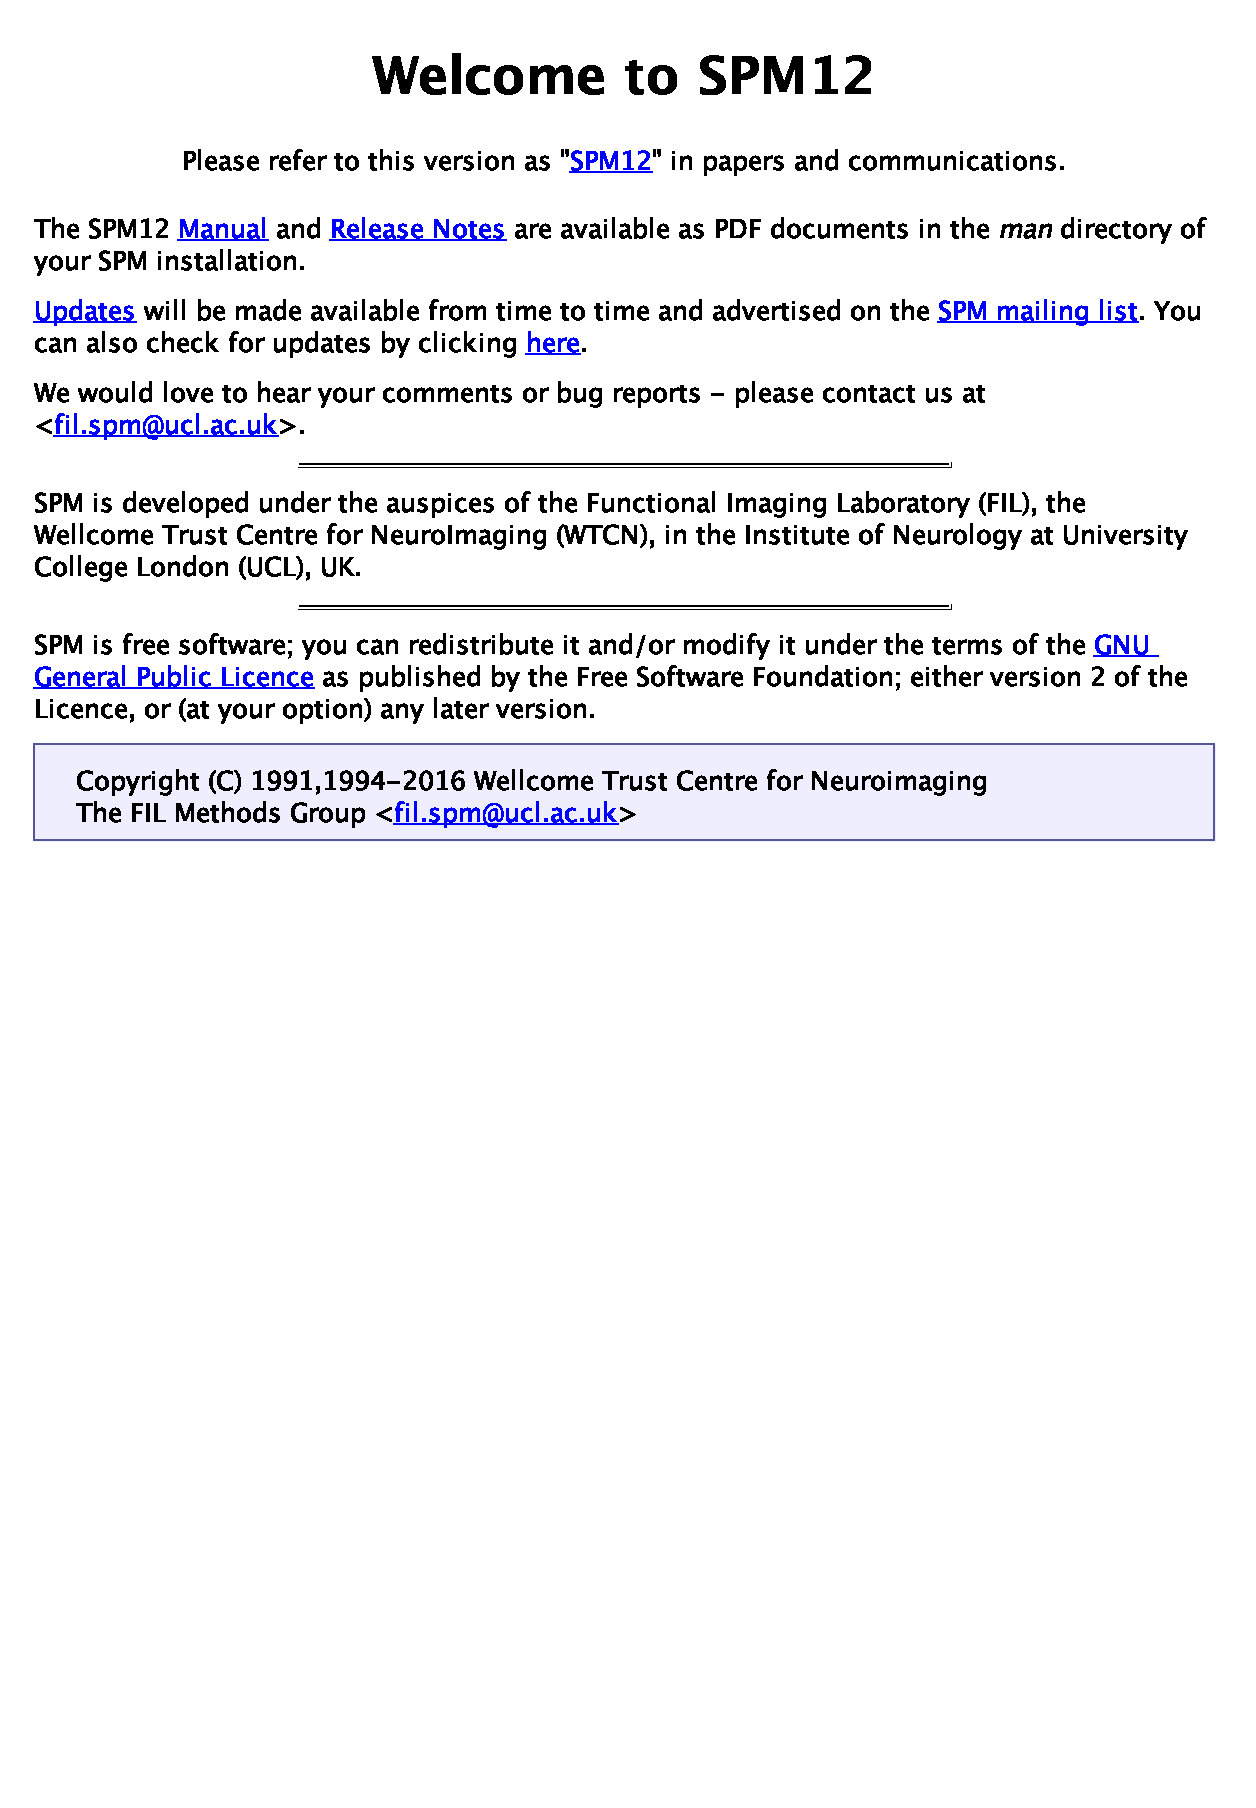

.

.

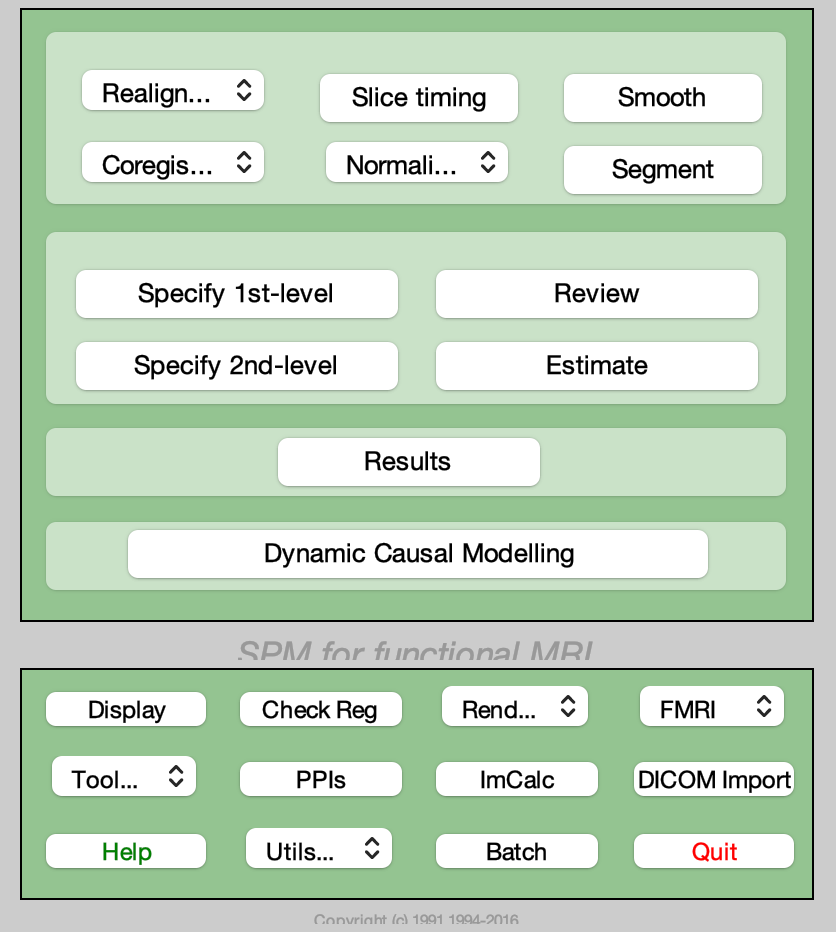

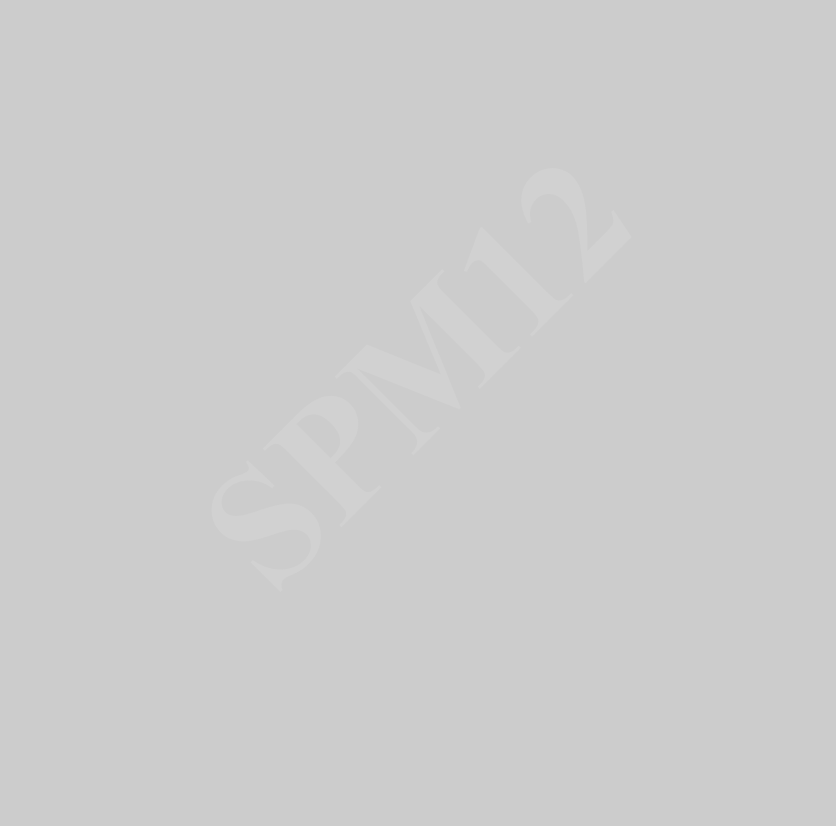

done

SPM present working directory:
	/Users/torwager/Dropbox (Dartmouth College)/COURSES/Courses_Dartmouth/2021_3_Spring_fMRI_Class/Labs_and_Lectures_for_Instructors/Labs_and_assignments/Lab_5/Pinel_data_sample_subject


spm fmri

## Prepare data and variables

### Setting up a first-level analysis: Ingredients

We're setting up for the first-level analysis.  We need five things:

**1) Brain data. **The functional fMRI data, preprocessed and ready for analysis (usually, realigned, warped to MNI space, and smoothed) 

- Here, we want "swr*" images, which are **S**moothed, **W**arped, and **R**ealigned

- Other scaling and "denoising" (artifact-removal) steps are sometimes done in preprocessing as well

**2) Task information. **Onset times, durations, and names for each event type (condition) of interest

- In BIDS standard format, these are in a .tsv file

- For SPM, we'll create cell arrays called **ons, durations,** and** names**

**3) Nuisance covariates.** Any custom nuisance covariates we want to add, including 

- "Spike" (indicator) regressors for outliers

- Movement parameters and their transformations

- Any other custom regressors, e.g., global CSF or aCompCorr regressors

- We want to be careful about how we choose these, to avoid multicolinearity with task regressors

- For SPM, we will save these in one matrix, **R**

- For BIDS/fmriprep, these are in *_desc-confounds_regressors.tsv

**4) Filter**. An intended HP filter cutoff in sec

    - SPM will add the high-pass filter when it does the analysis

**5) Contrast weights** for effects (comparisons across conditions) we care about

### Find and examine the brain data

#### Navigate to files

It's helpful to start in a folder with data in it, so you don't have to navigate extensively through the SPM file selection browser. 

pwd  % where am i now? (in terms of working directory, at least)

ans = '/Users/torwager/Dropbox (Dartmouth College)/COURSES/Courses_Dartmouth/2021_3_Spring_fMRI_Class/Labs_and_Lectures_for_Instructors/Labs_and_assignments/Lab_5/Pinel_data_sample_subject_INSTRUCTOR'

Use cd( ) to go to your sample subject directory. Drag and drop, or copy and paste the path from Terminal.

ls  % list files here

SPM_onsets_and_nuisance_regressors.mat
c1sub-sid001567_acq-MPRAGE_T1w.nii
c2sub-sid001567_acq-MPRAGE_T1w.nii
c3sub-sid001567_acq-MPRAGE_T1w.nii
c4sub-sid001567_acq-MPRAGE_T1w.nii
c5sub-sid001567_acq-MPRAGE_T1w.nii
canlab_robust_reg_model1
mwc1sub-sid001567_acq-MPRAGE_T1w.nii
mwc2sub-sid001567_acq-MPRAGE_T1w.nii
mwc3sub-sid001567_acq-MPRAGE_T1w.nii
rp_sub-sid001567_task-pinel_acq-s1p2_run-03_bold.txt
rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.mat
rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii
rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii.gz
rsub-sid001567_task-pinel_acq-s1p2_run-03_bold_reorient.mat
spm_model1
sub-sid001567_acq-MPRAGE_T1w.nii
sub-sid001567_acq-MPRAGE_T1w.nii.gz
sub-sid001567_acq-MPRAGE_T1w_reorient.mat
sub-sid001567_acq-MPRAGE_T1w_seg8.mat
sub-sid001567_task-pinel_acq-s1p2_run-03_bold.json
sub-sid001567_task-pinel_acq-s1p2_run-03_bold.mat
sub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii
sub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii.gz
sub-sid001567_tas

#### Find the functional run and examine the data

It's always important to look at your data!  Check: Do the brains look like brains? is the range of data values what you expected? Are there crazy outliers? Does the image space match the template space? Are the images relatively homogenous, or do some appear to be really different, i.e., on the same scale?

We'll use CANlab object-oriented tools, specifically the **fmri_data** object, to load the preprocessed data and make a summary plot. Here, we want "swr*" images, which are **S**moothed, **W**arped, and **R**ealigned...and hopefully thus ready for analysis.

preprocessed_image_name = 'swrsub-sid001567_task-pinel_acq-s1p2_run-03_bold.nii';

% Load the images into an fmri_data object
dat = fmri_data(preprocessed_image_name);

Using default mask: /Users/torwager/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 145720800 bytes
Loading image number:   150
Elapsed time is 3.490070 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
.fullpath should have image name for each image column in .dat
Attempting to expand image filenames in case image list is unexpanded 4-D images


Calculating mahalanobis distances to identify extreme-valued images
...based on union of corr...Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 22.67%
Expected 7.50 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 1 
Uncorrected: 6 images		Cases 1 2 3 4 5 6 

...and cov...Retained 2 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 18.67%
Expected 7.50 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 1 
Uncorrected: 6 images		Cases 1 2 3 4 5 6 

done.
Outliers:
Outliers after p-value correction:
Image numbers: 1 

Image numbers, uncorrected: 1 2 3 4 5 6 


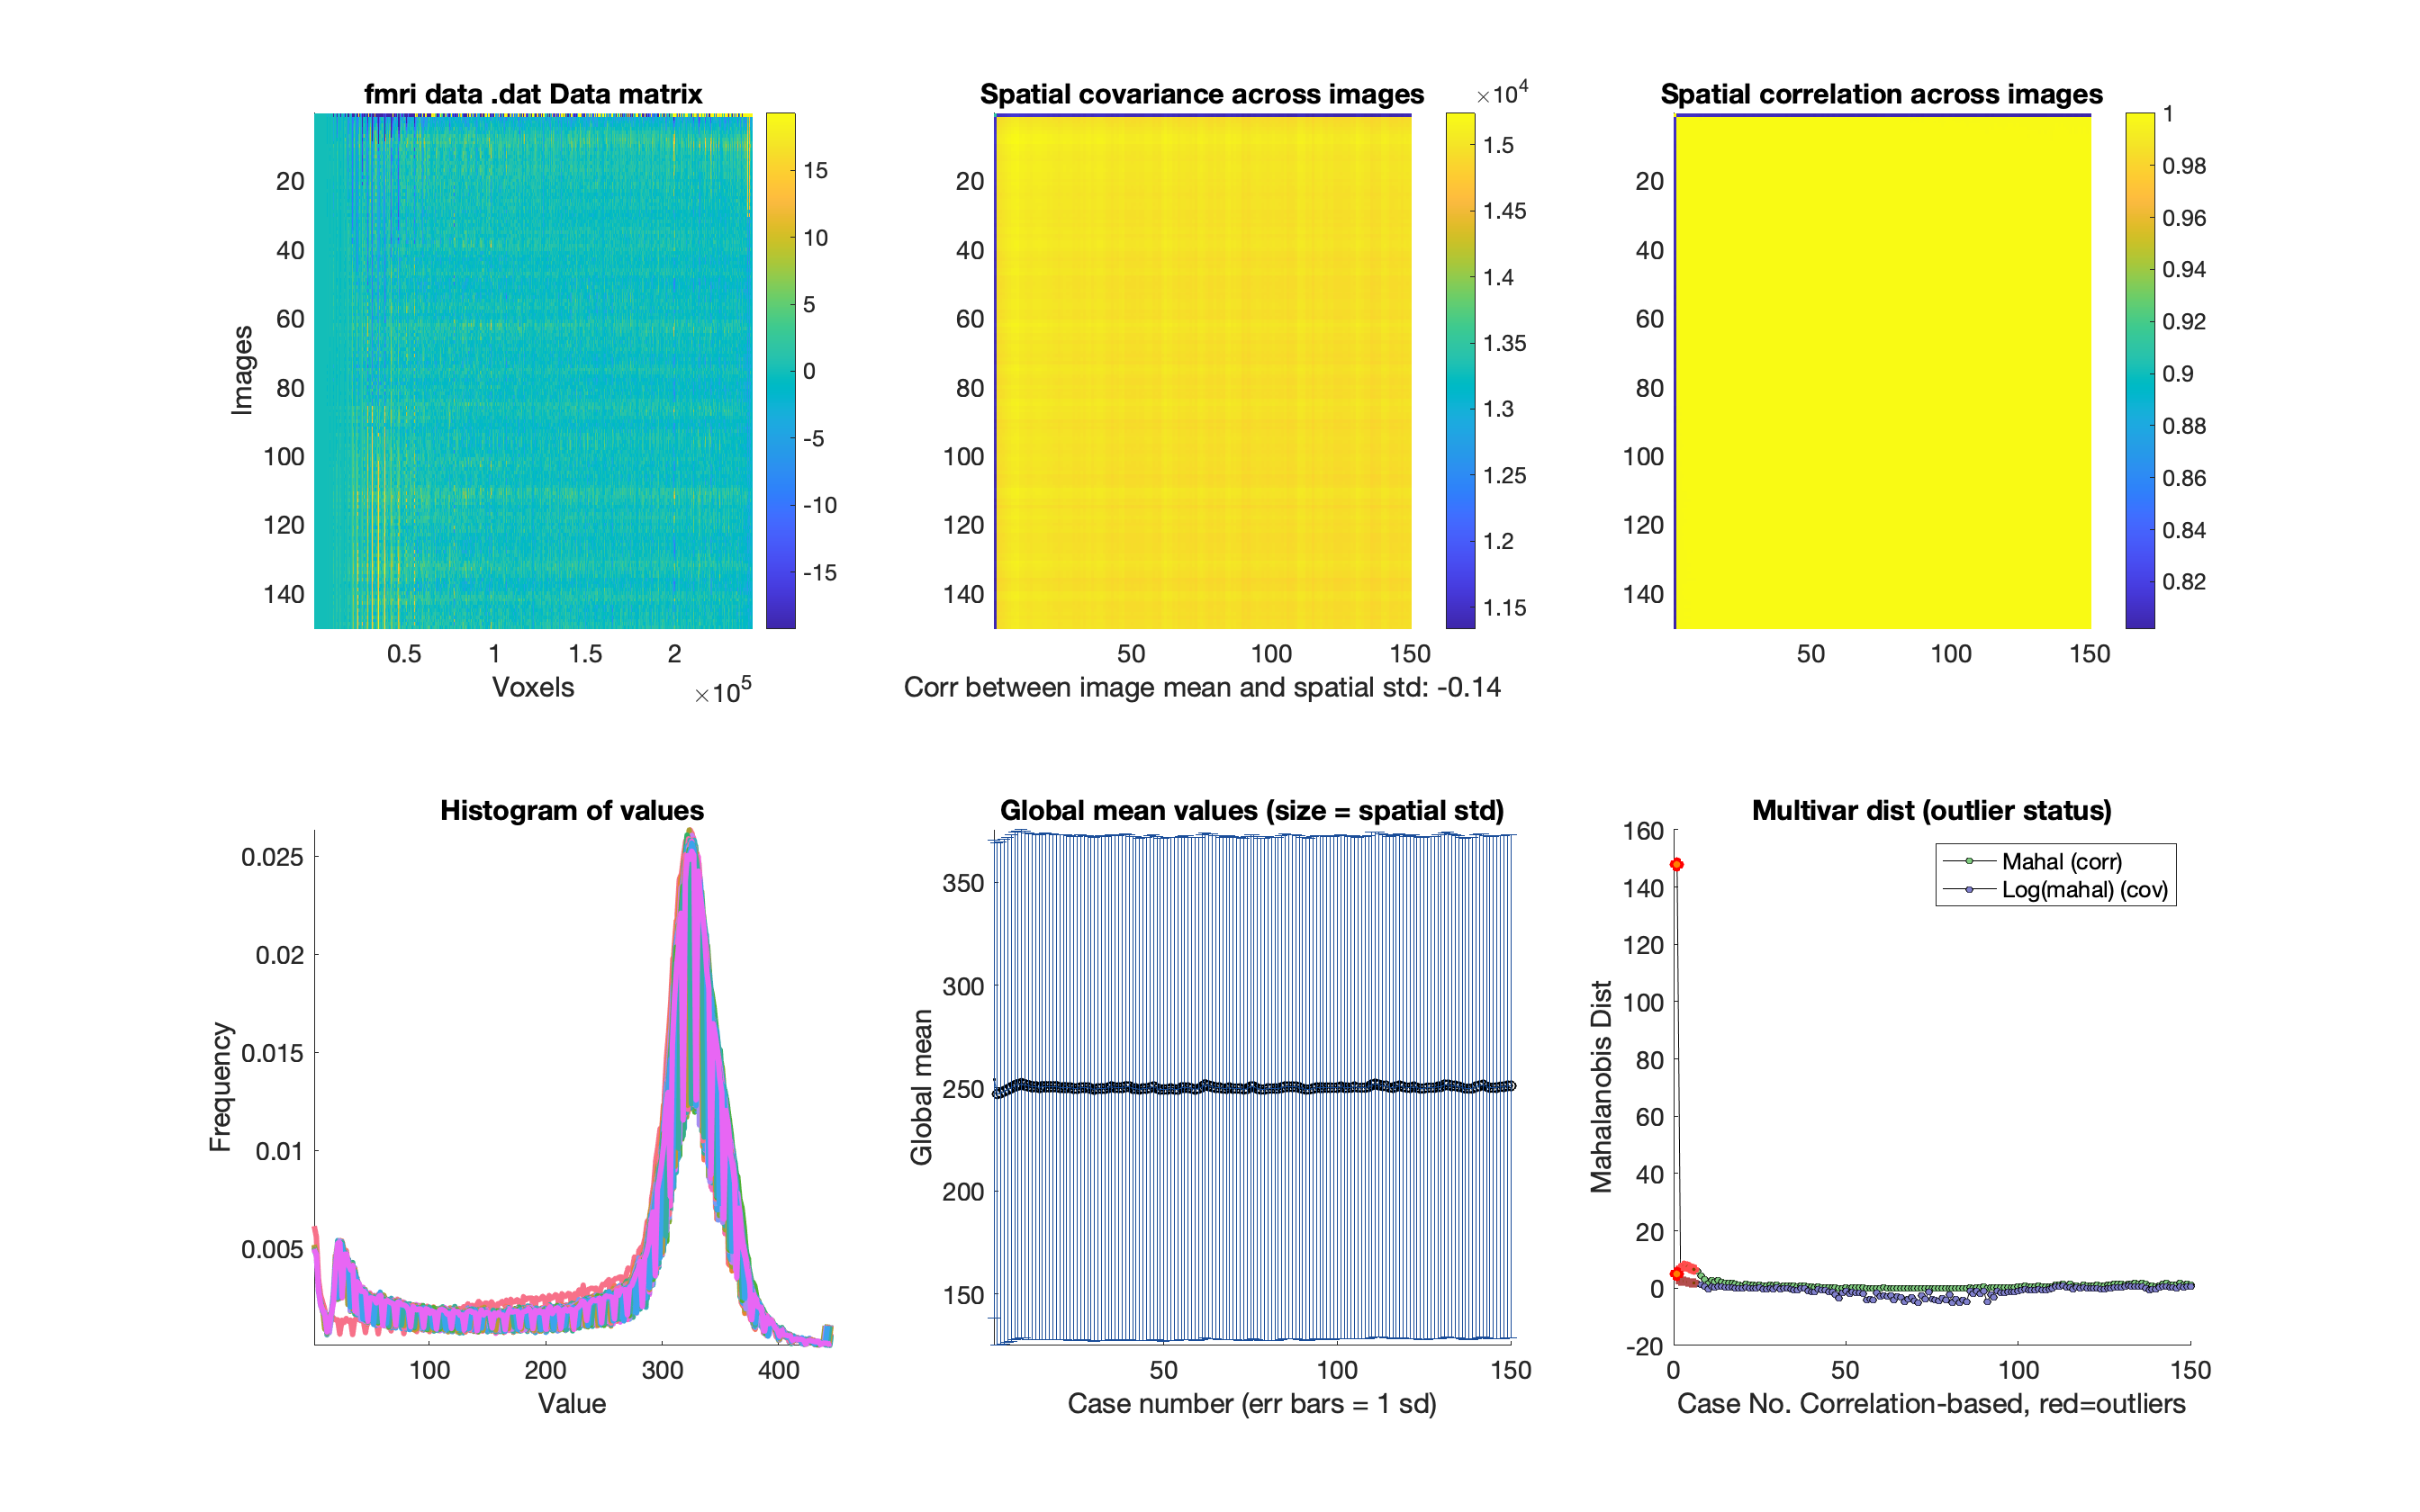

Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions


Grouping contiguous voxels:   1 regions



% Plot the images. Save potential outliers.
[wh_outlier_uncorr, wh_outlier_corr] = plot(dat);

#### Create "spike" regressors

This gives us our first set of potential nuisance covariates, related to "spikes"

We'll convert these to column vectors, suitable for regressors. There aren't too many, so the more liberal "uncorr" may be a better bet (there's no definitive right answer.) We'll define the matrix R`_spikes`, where **R **will be used for **R**egressors of no interest (nuisance regressors). You can unpack the code below on your own if you want to - one note is that we have to tell it how many images we have (size(dat.dat, 2)) so the matrix has a row for every image.

% make outlier list into an indicator matrix
R_spikes = intercept_model(size(dat.dat, 2), find(wh_outlier_uncorr));
R_spikes = R_spikes(:, 2:end);  % remove initial intercept column

% If you have the neural net toolbox, Matlab's ind2vec( ) will also do  this:
%R_spikes = full(ind2vec(find(wh_outlier_uncorr)', size(dat.dat, 2))); 

#### Questions to answer:

- Write a short summary of what you see here, and how you might respond to each of the preliminary data check questions above.

- Where are the spikes located, and is there a systematic pattern? What might this be related to?

### Load task onset times and create a simple design matrix

Previously, we loaded the BIDS-format .tsv file and turned it into a set of regressors. Along the way, we created a cell array ( which uses **{ } **) with the onset times and durations of events. That's what we'll use here.

Note that the key variables we'll need later are as follows. SPM will ask us to enter these. More advanced users can also enter the cells arrays directly into the SPM batch system. 

- **onsets**

- **durations**

- **names**

Each of these is a cell array, with one cell per condition. Each cell of ons contains a vector of event onsets for that condition. Each cell of durations contains a vector of event durations (in seconds or TRs, but we'll use seconds by convention). 

% Load the onsets file into a table object in matlab

taskdata = readtable('sub-sid001567_task-pinel_acq-s1p2_run-03_events.tsv', 'FileType', 'text');

% Use a CANlab function to extract the conditions (event types) and which
% events belong to each type
[indic, names] = string2indicator(taskdata.trial_type);
indic = logical(indic);

% Get a cell array of onsets for each condition
[onsets, durations, ons_with_durations] = deal(cell(1, length(names)));

for i = 1:length(names)
    onsets{i} = taskdata.onset(indic(:, i));
    
    durations{i} = taskdata.duration(indic(:, i));
    
    % This used just for plotting purposes just below
    ons_with_durations{i} = taskdata.onset(indic(:, i)); 
    ons_with_durations{i}(:, 2) = taskdata.duration(indic(:, i));
end

Now, we've extracted the information in a format we can use to construct a design matrix. Let's try it. 

*Note* that we need to know the TR for this! It's 2 sec. In BIDS formatted data, this can be found in the ".json sidecar" file, in the "RepetitionTime" field. We also need the scan length in sec, which in this case is 300 sec or 5 min.

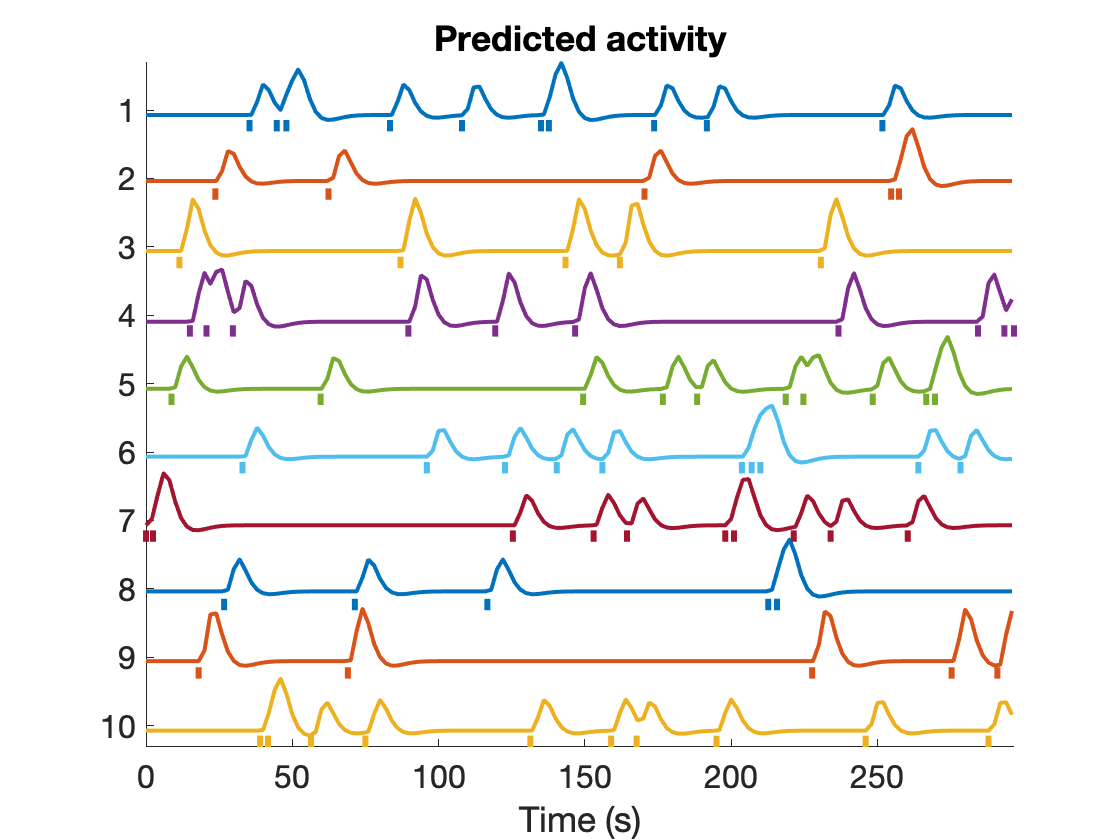

TR = 2;
X = onsets2fmridesign(onsets, TR, 300);

% let's plot it
plotDesign(onsets, [], TR);

This returns the design matrix, X.

We can look at the Variance Inflation Factors to see whether there are mulitcolinearity issues or not. We'll use the 'plot' option and save the handle to this figure so we can re-activate it and add things later:

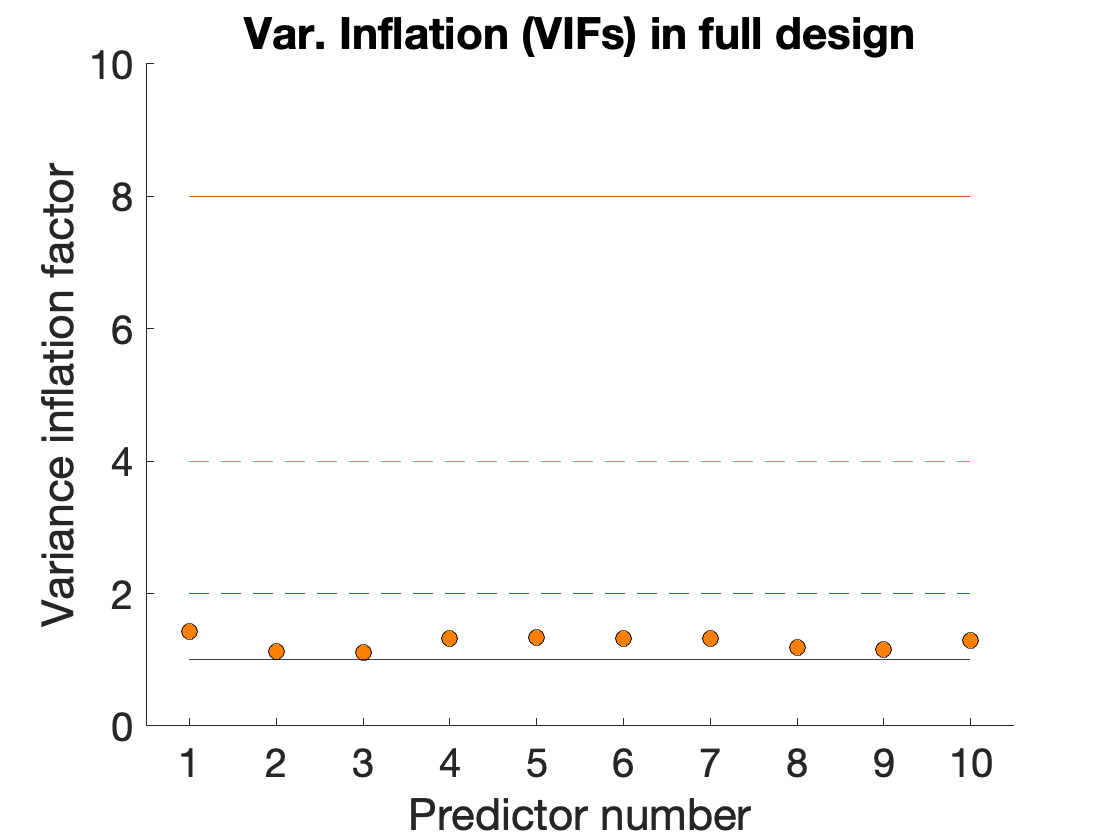

Variance inflation: 1 (black line) = minimum possible (best)
Successive lines indicate doublings of variance inflation factor.
Red boxes have extremely high VIFs, perfect multicolinearity


fig_han = create_figure('vifs'); % Get handle to current figure

vifs = getvif(X, 0, 'plot');

#### Load and create transformations of motion parameter estimates

rp_file = 'rp_sub-sid001567_task-pinel_acq-s1p2_run-03_bold.txt';
rp = importdata(rp_file);

Let's plot them:

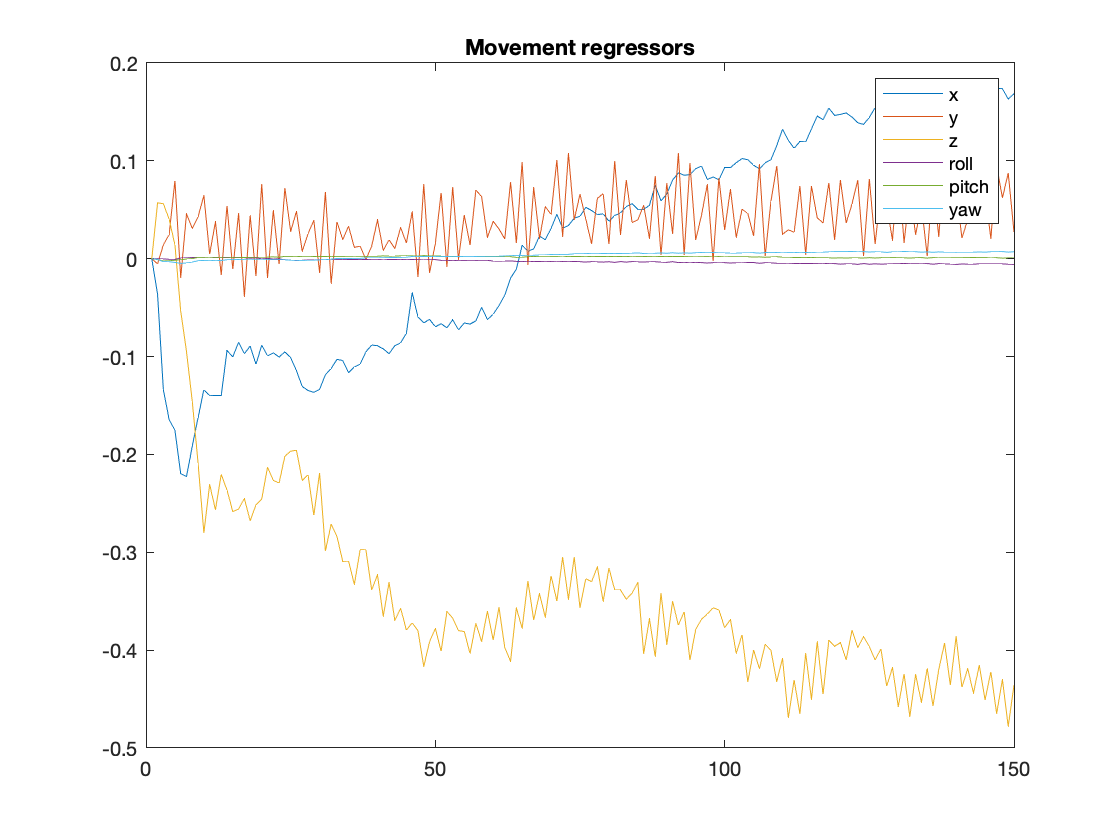

figure; plot(rp);
legend({'x' 'y' 'z' 'roll' 'pitch' 'yaw'});
title('Movement regressors')

Let's expand the set of motion parameters and add those. When we calculate the quadratic terms, scale (and mean) DOES matter, so we'll zscore the regressors to center them on 0, which makes the quadratic terms capture a "U shaped" effect, orthogonal to the original rp regressors. 

[~, d_rp] = gradient(rp);  % gradient estimates the derivative. ~ marks an irrelevant output for us that is "thrown away"

R_mvmt = zscore([rp d_rp]);  % z-score to make each column zero-mean

quadterms = R_mvmt .^ 2;

R_mvmt = [R_mvmt zscore(quadterms)]; % z-score here for convenience in display

#### Nuisance regressors based on DVARS, or root mean square successive differences (RMSSD)

Images usually change slowly over time, and sudden changes in intensity can also often be a sign of bad things -- head movement artifact or gradient misfires, interacting with the magnetic field to create distortion across the brain.

RMSSD tracks large changes across successive images, regardless of what the sign of the changes is or where they are. In addition, images with unusually high *spatial standard deviation across voxels* may be outliers with image intensity distortions in some areas of the image but not others (e.g., bottom half of brain vs. top half, or odd vs. even slices).

The CANlab method *rmssd_movie( )*, for *fmri_data* objects, creates a visual movie so you can see what the image-to-images changes are. It pauses where they're unusual. 

It also returns a matrix `rmssd_outlier_regressor_matrix, `which has an indicator regressor (1 or 0 values) for every image that is quite different from the preceding ones (the pause point in the movie). This is based on two things: (1) rmssd being > a cutoff number of standard deviations from the mean, (2) spatial standard deviation of the images being > a cutoff number of standard deviations from the mean. The cutoff is 3 s.d. by default. This matrix can be added to your design matrix as a set of nuisance covariates of no interest.

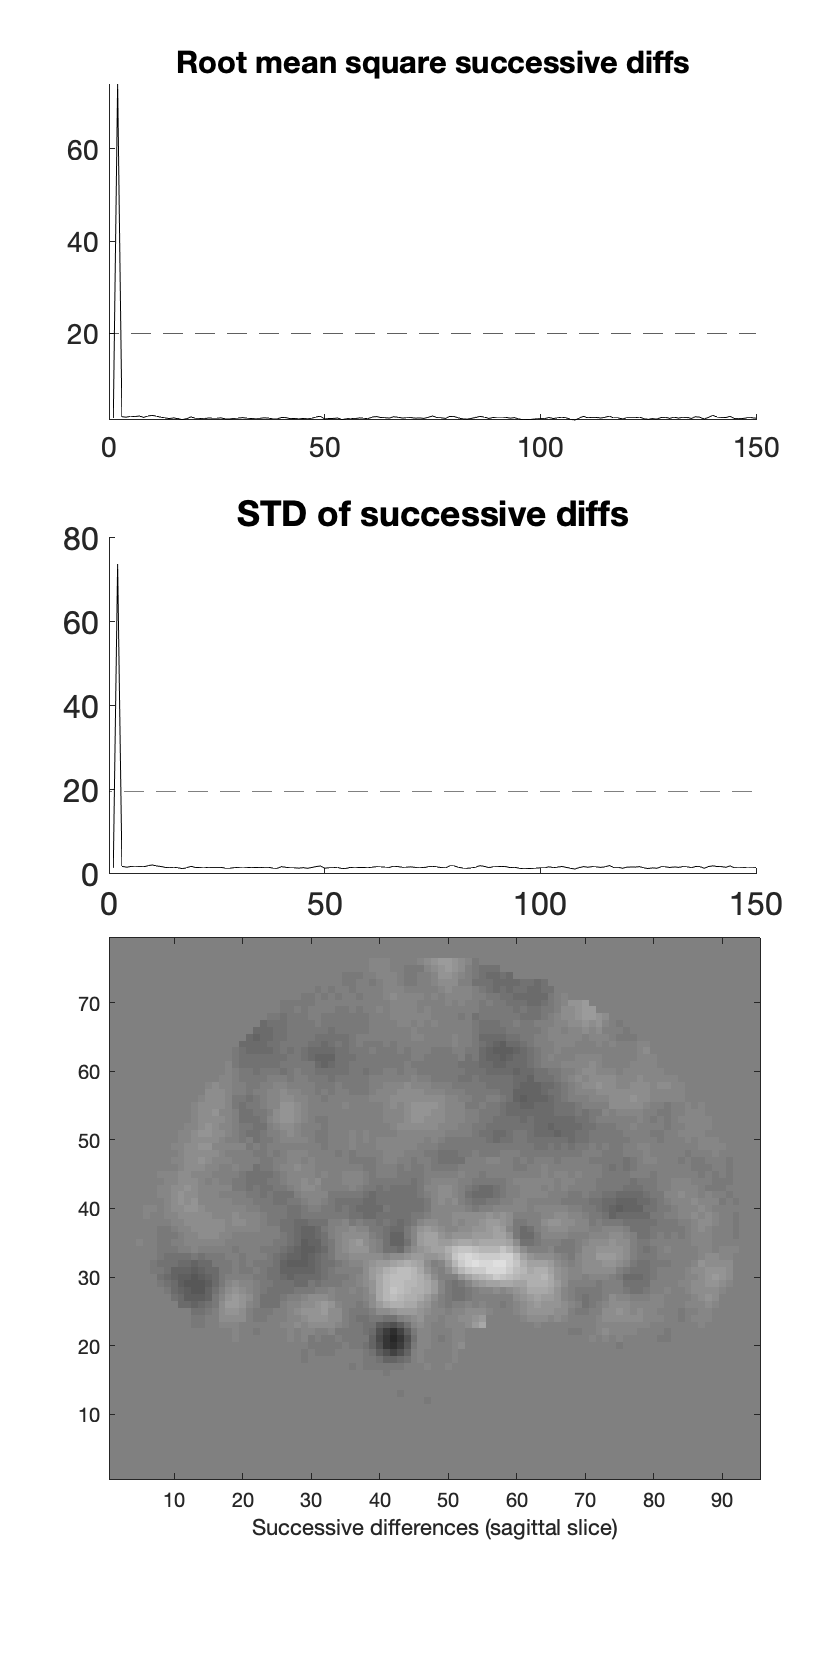

[rmssd, rmssd_outlier_regressor_matrix] = rmssd_movie(dat);


R_dvars = rmssd_outlier_regressor_matrix;  % save these


#### Questions to answer:

- Describe what's happening in the image during any outliers you observe. What kind of acquisition or other problem might have caused this?

- Why are "spike"/outlier regressors saved in different columns in the design matrix?

#### Create and save final nuisance covariates

Now, we'll combine all the nuisance covariates into one set, **R**. If any of your component matrices are the wrong size, you'll get an error! Try `whos R*` to check if needed.

R = [R_spikes R_dvars R_mvmt];


We may have to get rid of redundant columns of C:

R = unique(R', 'rows', 'stable')';  % remove any redundant rows. Keep the same order of regressors otherwise.

#### Check the design matrix with nuisance covariates

Finally, let's re-calculate the VIFs for task regressors and add them to our original plot:

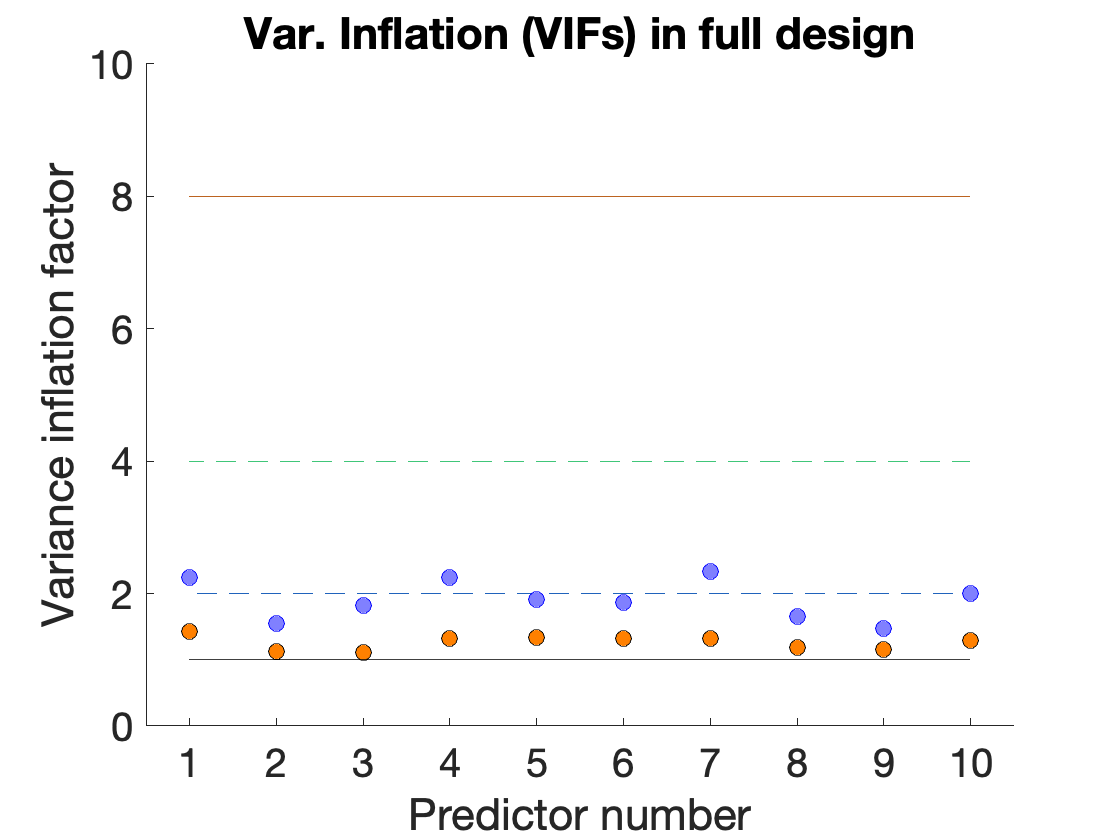

X3 = [X R];

figure(fig_han)   % re-activate the VIF figure

vifs3 = getvif(X3);

han = plot(vifs3(1:10), 'bo', 'MarkerSize', 8, 'MarkerFaceColor', [.5 .5 1]);

As always, VIFS that are  high are bad, and VIF = 1 is perfect in terms of multicolinearity. If they go up a lot after including nuisance covariates, the task regressors are correlated with the nuisance regressors.

#### Questions to answer:

- How have the VIFs changed? 

- What is the impact of changes in VIFs on statistical power? On the validity of contrasts comparing these? Consider potential effects on bias and variance, and how this relates to power.

### Create contrasts

Contrasts won't be needed until *after* we estimate the model, when we get "Results" in SPM, but let's create some now so we have all the information we need in one place. Let's look at the names:

names'

ans = 10×1 cell array
    {'audio_computation'      }
    {'audio_left_hand'        }
    {'audio_right_hand'       }
    {'audio_sentence'         }
    {'horizontal_checkerboard'}
    {'vertical_checkerboard'  }
    {'video_computation'      }
    {'video_left_hand'        }
    {'video_right_hand'       }
    {'video_sentence'         }


 We'll enter a matrix **C.weights**, with each column as a different contrast across the 10 names, and each row a condition (so: 10 rows).  We'll enter them as row vectors and then transpose them using the transpose operator, **'**.  C will be a structure variable, so it can save both weights (values) and names. We'll also save names for each contrast. 

It's good practice not to use spaces or special characters in names, as they may be used for file or variable names, which can cause errors.

C.weights = [1 1 1 1 0 0 -1 -1 -1 -1];           C.names = {'Audio_vs_video'};

C.weights(2, :) = [0 0 0 0 1 1 0 0 0 0];         C.names{2} = 'Checkerboard_vs_other';

C.weights(end+1, :) = [0 -1 1 0 0 0 0 -1 1 0];   C.names{end+1} = 'Right_vs_left_hand';
C.weights(end+1, :) = [2 -1 -1 0 0 0 2 -1 -1 0]; C.names{end+1} = 'Computation_vs_Motor';
C.weights(end+1, :) = [0 -1 -1 2 0 0 0 -1 -1 2]; C.names{end+1} = 'Language_vs_Motor';
C.weights(end+1, :) = [0 0 0 0 1 -1 0 0 0 0];    C.names{end+1} = 'Horiz_vs_Vert_checkerboard';

C.weights = C.weights';  % make conrasts columns, by convention

#### Questions to answer:

- Describe what's happening in the image during any outliers you observe. What kind of acquisition or other problem might have caused this?

- Why are the contrast weights sometimes 2 in the example? Is this a valid contrast, and if so, why?

- If you divided contrast weights by 2 for any of the contrasts, what will change when you estimate them? What won't change?

- Consider dividing the weights [0 -1 1 0 0 0 0 -1 1 0] by two. What is the semantic interpretation of the hypothesis tested before versus after the division.

### Save your work

Now we should have everything we need to build the design in SPM!  It's always a good idea to save prepared variables before they are entered into SPM, etc., so let's save a .mat file with the key variables: 

- **onsets**

- **durations**

- **names**

- **R**

- **C**

save SPM_onsets_and_nuisance_regressors onsets durations names R C

% Check what we've done
ls -lt *mat

-rw-r--r--  1 torwager  staff    28650 May  5 16:38 SPM_onsets_and_nuisance_regressors.mat
-rw-r--r--@ 1 torwager  staff  5722896 May  2 22:30 sub-sid001567_acq-MPRAGE_T1w_seg8.mat
-rw-r--r--@ 1 torwager  staff    19392 May  1 15:13 rsub-sid001567_task-pinel_acq-s1p2_run-03_bold.mat
-rw-r--r--@ 1 torwager  staff      312 May  1 15:13 rsub-sid001567_task-pinel_acq-s1p2_run-03_bold_reorient.mat
-rw-r--r--@ 1 torwager  staff      312 May  1 15:09 sub-sid001567_acq-MPRAGE_T1w_reorient.mat
-rw-r--r--@ 1 torwager  staff    19392 Feb 27  2020 sub-sid001567_task-pinel_acq-s1p2_run-03_bold.mat



 You can reload this file and recover these variables without having to type them in.

## Specify the model in SPM

#### Create a 1st-level model folder

First, create a folder where you want SPM to save the results. It's a good idea to include the subject name. But here, this is just a test subject, so we'll use:

mkdir spm_model1

Then, push this button:

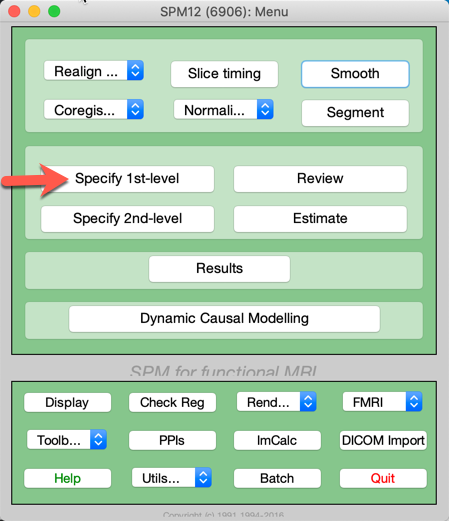

Then, fill in the fields. We'll select our analysis directory and other parameters. Make sure you select all the images, by (1) setting the filter to `swr.*` and (2) expanding the "Frames" from 1:150 (or however many images you have). Then click on the first one, and shift+click on the last one.

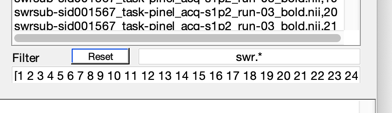

 Because we've saved the .mat file with onsets, etc., we can enter the file name directly in "**Multiple Conditions**" instead of typing in all the onsets and names.  Because this file also contains the nuisance covariates in a variable R, we can also use the same file to specify "**Multiple Regressors**". 

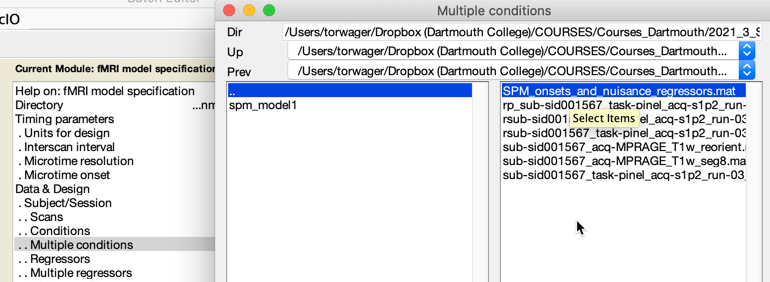

In the example below, I added a "mask" of gray matter (c1). But it's typical for multi-subject analyses to estimate within a whole-brain mask.

When you're done, it should look something like this. Actually, there's one mistake - can you spot it? (hint: AskMay in pig Latin).

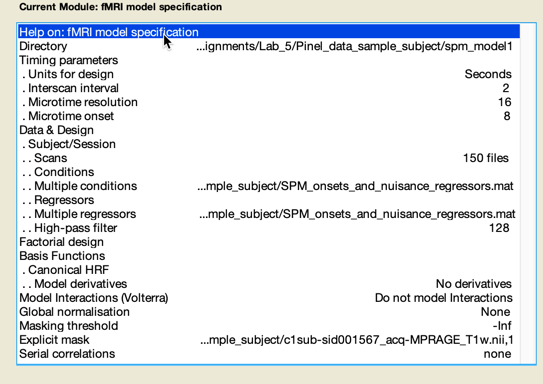

**Then press GO (Green Arrow)**

We get this:

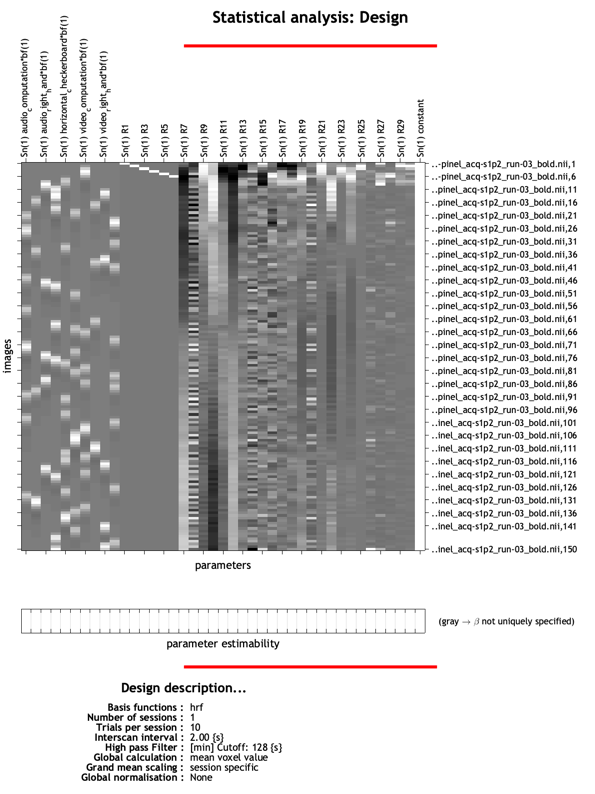

Yep, all our regressors look like they loaded in correctly. 

Now, we have an **SPM.mat** file saved. This file saves a structure, called SPM, with lots of information about your analysis.

ls spm_model1

#### Questions to answer:

- Which key pieces of information in the regression have been calculated at this point?

- Which are the task regressors and which are nuisance in the design matrix above?

### Estimate the model

This is where you estimate the betas, or regression parameter estimates, for each regressor in each voxel.

Fitting the model involves solving the equation $y=X{\beta}}$ for unknown vector $\beta$, where $y$ is a brain time series (a vector), $X$is the model or "design matrix", and $\hat{\beta}$ is a vector of estimates for the unknown regression slopes or "parameters". ${\hat}$ or "hat" means something that is estimated from the data during model fitting. The solution is:

${\hat{\beta}}=(X^TX)^{-1}X^Ty$. 

This projects the data (*y*) onto the subspace spanned by the columns of *X, *and provides a unique, optimal solution for $\hat{\beta}$, as long as the columns of X are not perfectly colinear. The fitted response $\hat{y}$ is the "reconstructed" data, as close as I can get to the data using a linear combination of model predictors.

Each voxel contains a data vector $y$, a time series. The model is estimated for each voxel in the brain separately. This is what makes the model a "mass univariate" model, as many separate regressions are run. The "beta images" saved by SPM (**beta_00xx.nii) **are collections of these values across all the regressions.

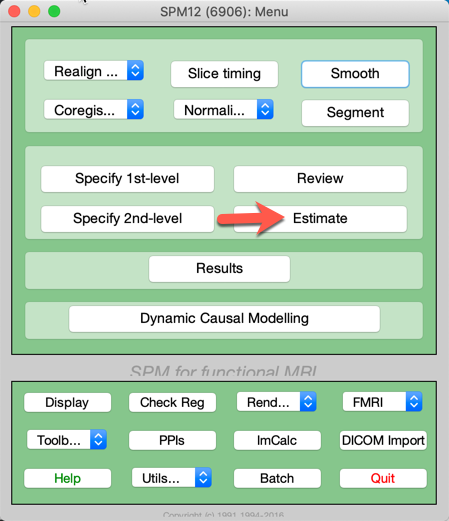

We'll select the SPM.mat file, and stick with the "classical" option. 

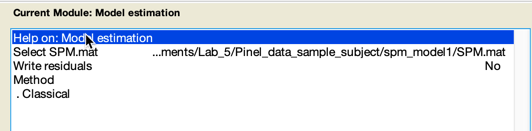

Hit go!

Now, the **SPM.mat** file is updated. In addition, we have "beta images" -- one per condition!

ls spm_model1

#### Questions to answer:

- Which additional key information in the regression model has been calculated now?

### Specify contrasts and get results

At this stage, we specify contrasts -- which are really hypotheses about differences -- and estimate statistic maps for inference. Before pushing the button, we'll list the contrast names we defined so we can copy and paste:

C
C.names

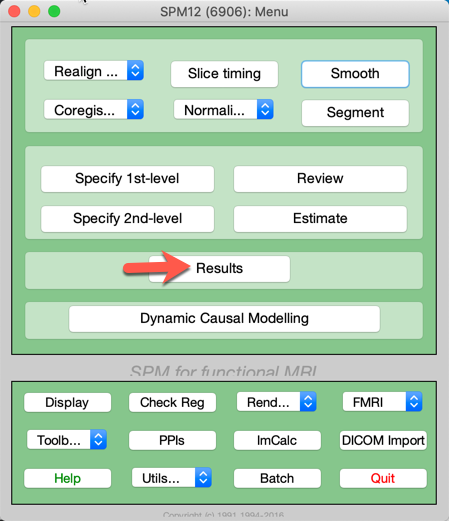

Each conrast must be entered as a row vector and named. Since we defined the weights, we don't have to copy and paste them in. We can enter them like this:

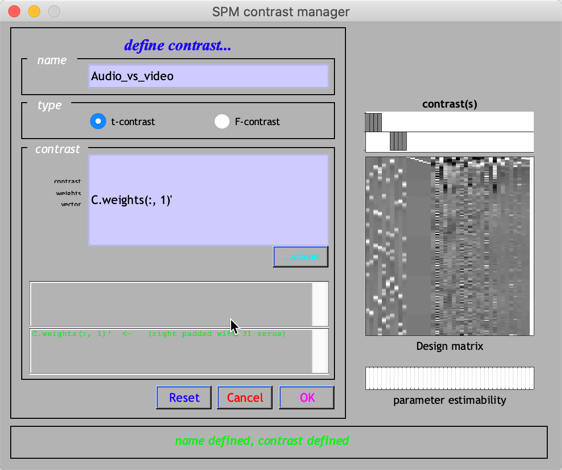

The plot at the right shows us which regressors have contrast weights of, e.g., 1 and -1 (the most typical values). 

When we estmate, we get a results map. We'll try "FDR" correction at 0.05. But you can play with other thresholds.

Some things you can do to explore the results:

- Click and drag the red arrow to move to different voxels.

- Ctrl+click or right click on the "Glass brain" to move to a cluster

- Double click the design matrix to return values to the command window

- Select "slices", "sections" or "montage" to plot activation clusters on slices (try plotting over the mwc1...nii image, which is the MNI-normalized gray-matter image.

- Write a thresholded results map, and load it and overlay it on the brain using CANlab tools (e.g., orthviews( ), montage( ), or surface( )

- Look at the mask. Load it in CANlab tools and overlay it on the standard MNI brain. Does it look as expected? Always look at your mask!

#### Questions to answer:

- Do you get any FWE-corrected results for the auditory stimulation contrast?

- What's one problem with the analysis as we've done it? (hint: AR model?)  Can you fix it and re-run the analysis?

- Can you identify auditory cortex in the results?

- Try some different contrasts. Do you see what you expect?

- Can you identify motor cortex? In what contrasts?

- Save a thresholded results map for a contrast of your choice. Load it into a CANlab fmri_data  object. Make a montage showing the results, and a surface image showing the results.

Here is a visualization of some of the display tools. Some will work on a thresholded SPM contrast map -- those that can be performed on a thresholded statistic_image object should generally work.